求均值为1.2345，标准差为6的正态分布在【0 10】 处的密度函数值与分布函数值

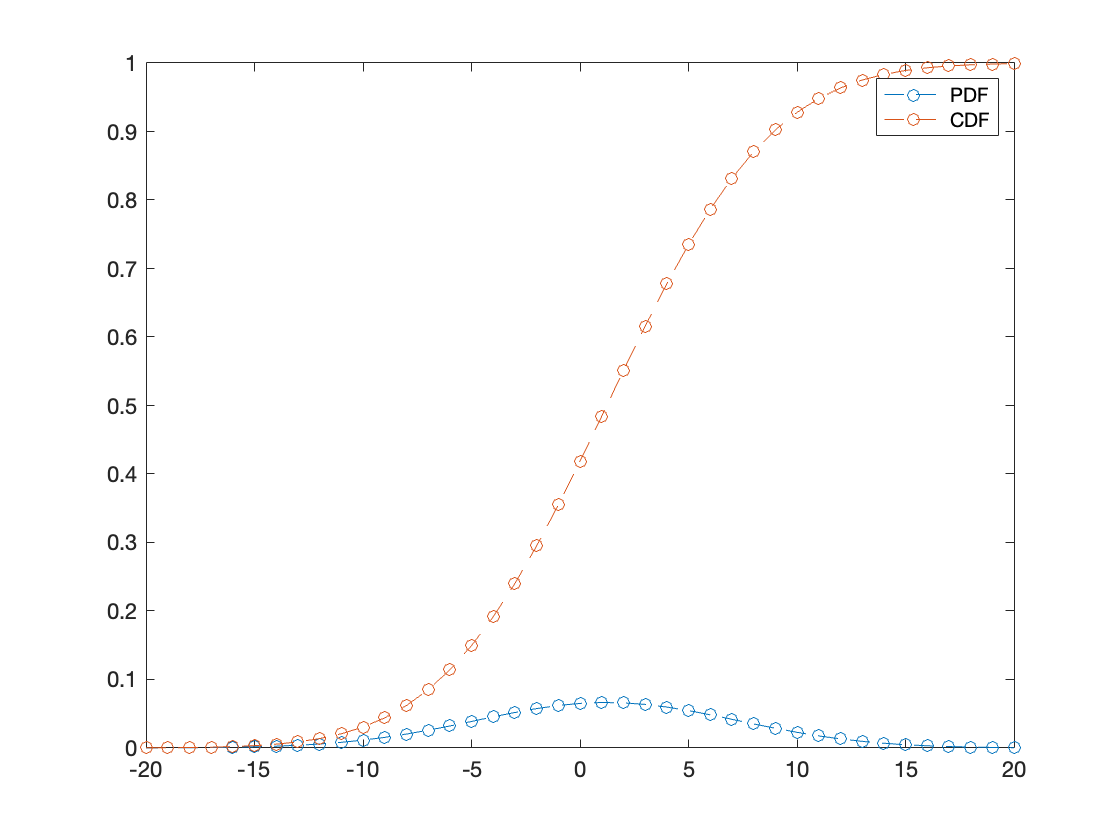

x = -20:20;    %产生一个向量
Y = normpdf(x, 1.2345, 6);    %求密度函数值
P = normcdf(x, 1.2345, 6);    %求分布函数值
figure,plot(x,[Y' P'],'o--');
legend('PDF','CDF');

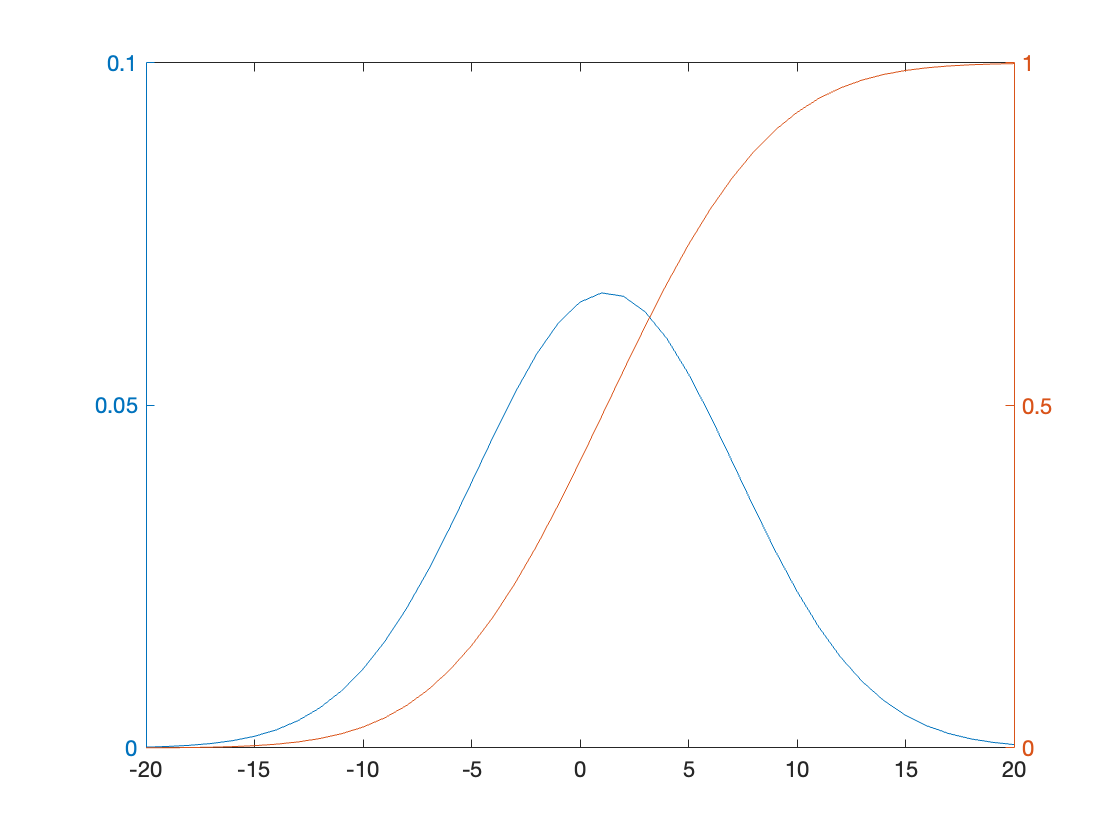

figure,plotyy(x,Y,x,P);

**调用normrnd函数生成1000×3的正态分布随机数矩阵，其中均值 为75，标准差为8，并作出各列的频数直方图**

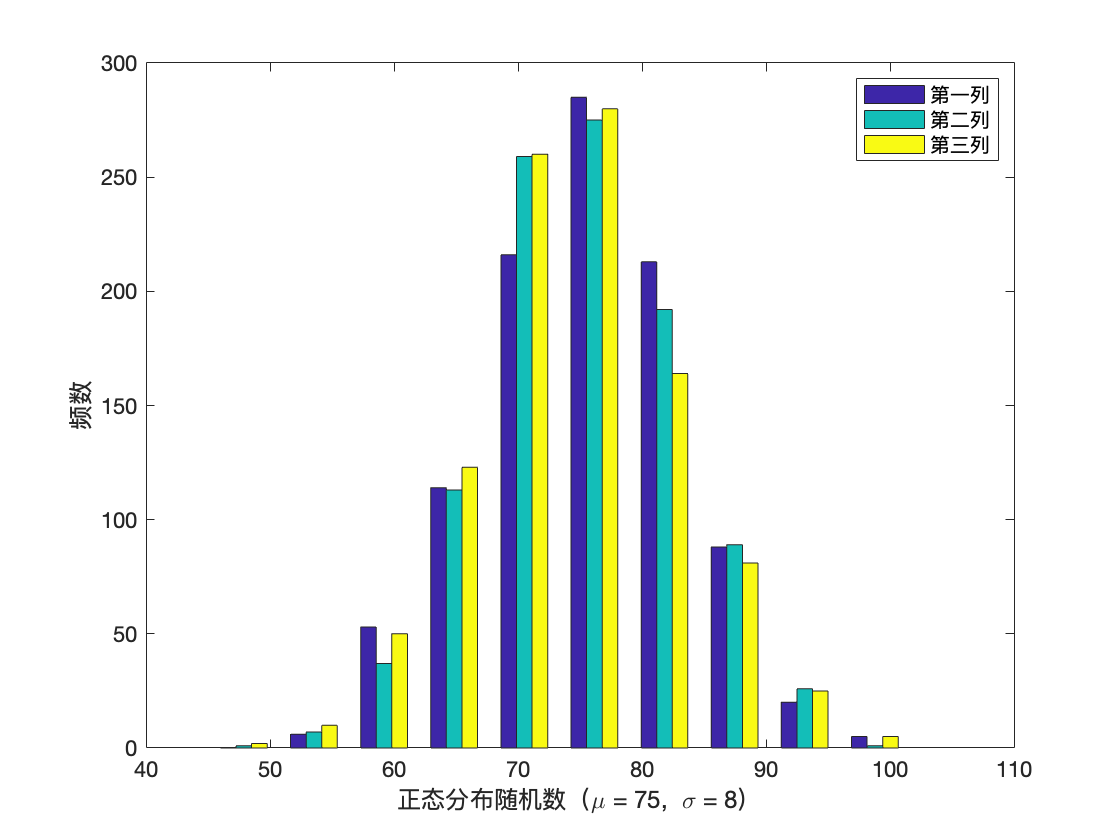

% 调用normrnd函数生成1000行3列的随机数矩阵x，其元素服从均值为75，标准差为8的正态分布
x = normrnd(75, 8, 1000, 3);
hist(x)    % 绘制矩阵x每列的频数直方图
xlabel('正态分布随机数（\mu = 75,  \sigma = 8）');    % 为X轴加标签
ylabel('频数');       % 为Y轴加标签
legend('第一列', '第二列', '第三列')    % 为图形加标注框

**调用random函数生成10000×1的二项分布随机数向量，然后作出频率直方图。其中二项分布的参数为 n=10，p=0.3 **

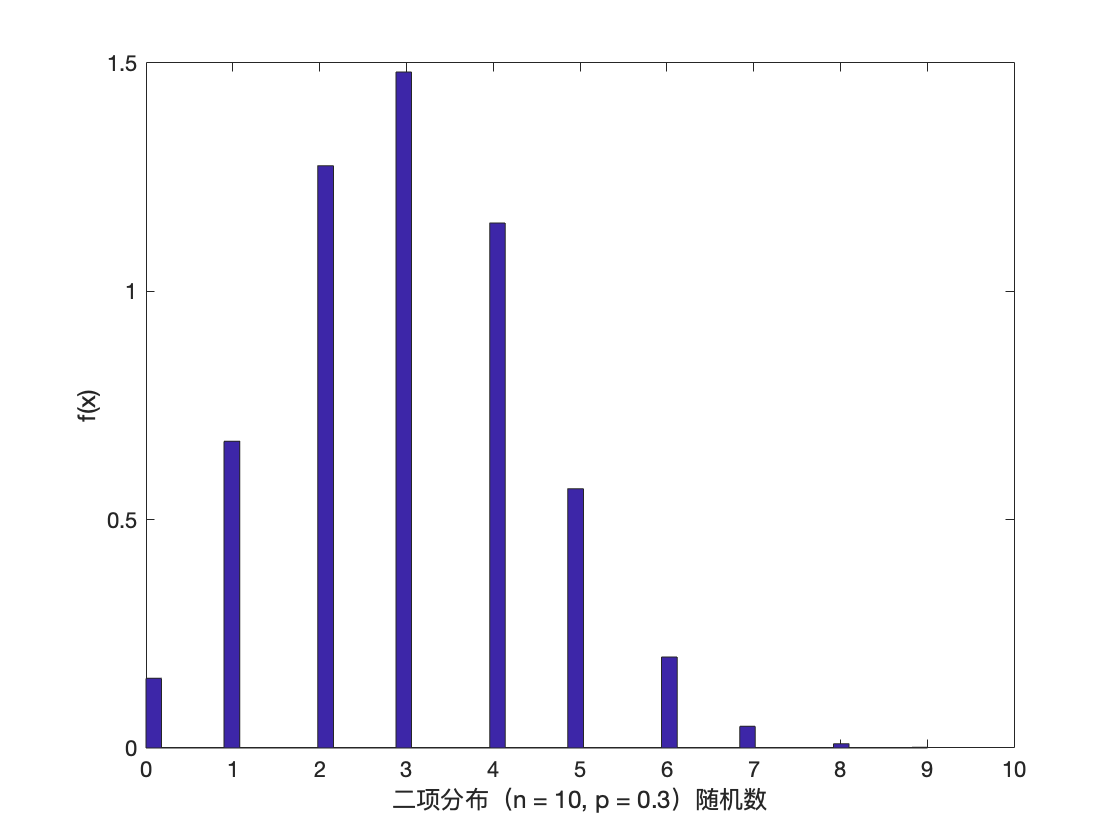

% 调用random函数生成10000行1列的随机数向量x，其元素服从二项分布B(10,0.3)
x = random('bino', 10, 0.3, 10000, 1);
[fp, xp] = ecdf(x);    % 计算经验累积概率分布函数值
ecdfhist(fp, xp, 50);    % 绘制频率直方图
xlabel('二项分布（n = 10, p = 0.3）随机数');    % 为X轴加标签
ylabel('f(x)');       % 为Y轴加标签

**调用random函数生成10000×1的卡方分布随机数向量，然后作出频率直方图，并与自由度为10的卡方分布的密度函数曲线作比较。其中卡方分布的参数（自由度）为 10**

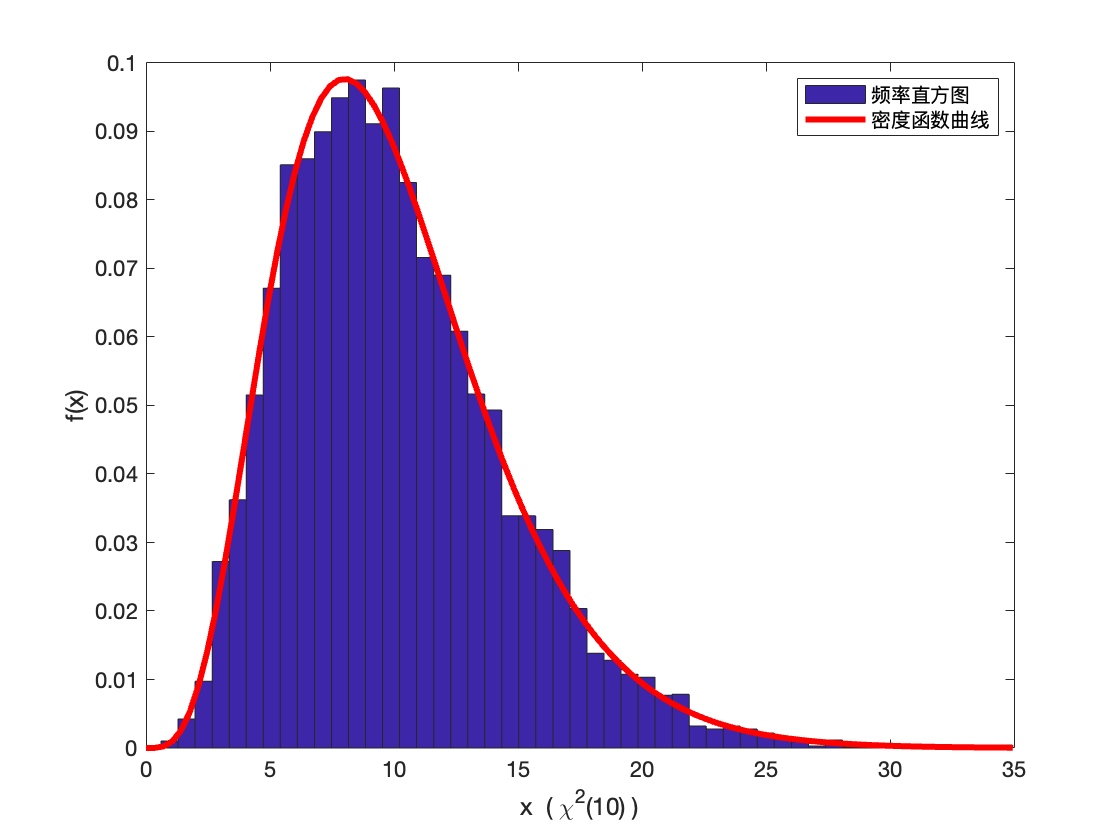

x = random('chi2', 10, 10000, 1);
[fp, xp] = ecdf(x);    % 计算经验累积概率分布函数值
ecdfhist(fp, xp, 50);    % 绘制频率直方图
hold on
t = linspace(0, max(x), 100);    
y = chi2pdf(t, 10);    
plot(t, y, 'r', 'linewidth', 3) 
xlabel('x  ( \chi^2(10) )');    % 为X轴加标签
ylabel('f(x)');       % 为Y轴加标签
legend('频率直方图', '密度函数曲线')    % 为图形加标注框

% *****************************统计量**************************************
%% 求均值
score = xlsread('examp7_1_1.xlsm','Sheet1','G2:G52');
score = score(score > 0);
score_mean = mean(score)

score_mean = 79

%% 求方差和标准差
SS1 = var(score)      % 计算方差

SS1 = 103

s1 = std(score)       % 计算标准差

s1 = 10.1489


%% 求最大值和最小值
score_max = max(score)

score_max = 98

score_min = min(score)

score_min = 49


%% 求极差
score_range = range(score)

score_range = 49


%% 求中位数
score_median = median(score) 

score_median = 80


%% 求分位数
score_m1 = quantile(score,[0.25,0.5,0.75])

score_m1 =    73.0000   80.0000   85.5000


score_m2 = prctile(score,[25, 50, 75])

score_m2 =    73.0000   80.0000   85.5000



%% 求众数
score_mode = mode(score) 

score_mode = 80


%% 求变异系数
score_cvar = std(score)/mean(score)

score_cvar = 0.1285


%% 求原点矩
A2 = mean(score.^2)

A2 = 6.3419e+03


%% 求中心矩
B1 = moment(score,1)

B1 = 0

B2 = moment(score,2)

B2 = 100.8980


%% 求偏度
score_skewness = skewness(score)

score_skewness = -0.7929


%% 求峰度
score_kurtosis = kurtosis(score)

score_kurtosis = 4.3324

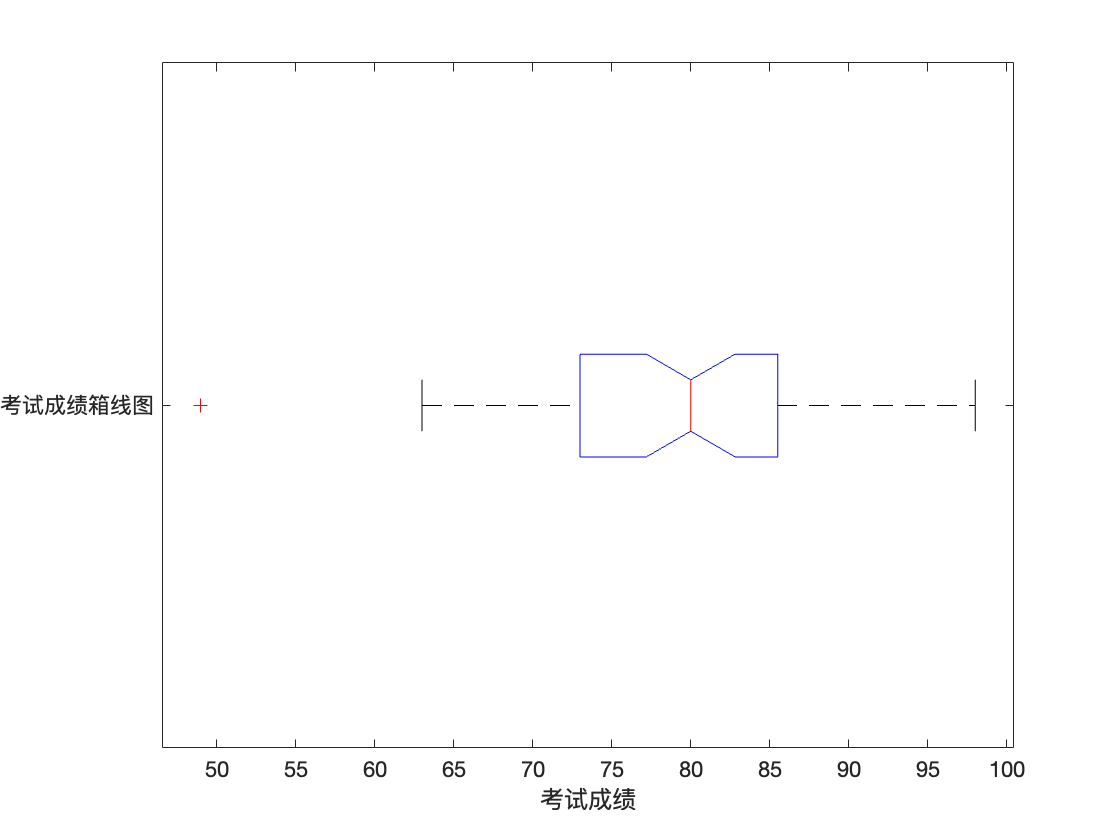

% *****************************统计图**************************************
%% 箱线图
figure;
boxlabel = {'考试成绩箱线图'};
boxplot(score,boxlabel,'notch','on','orientation','horizontal')
xlabel('考试成绩');

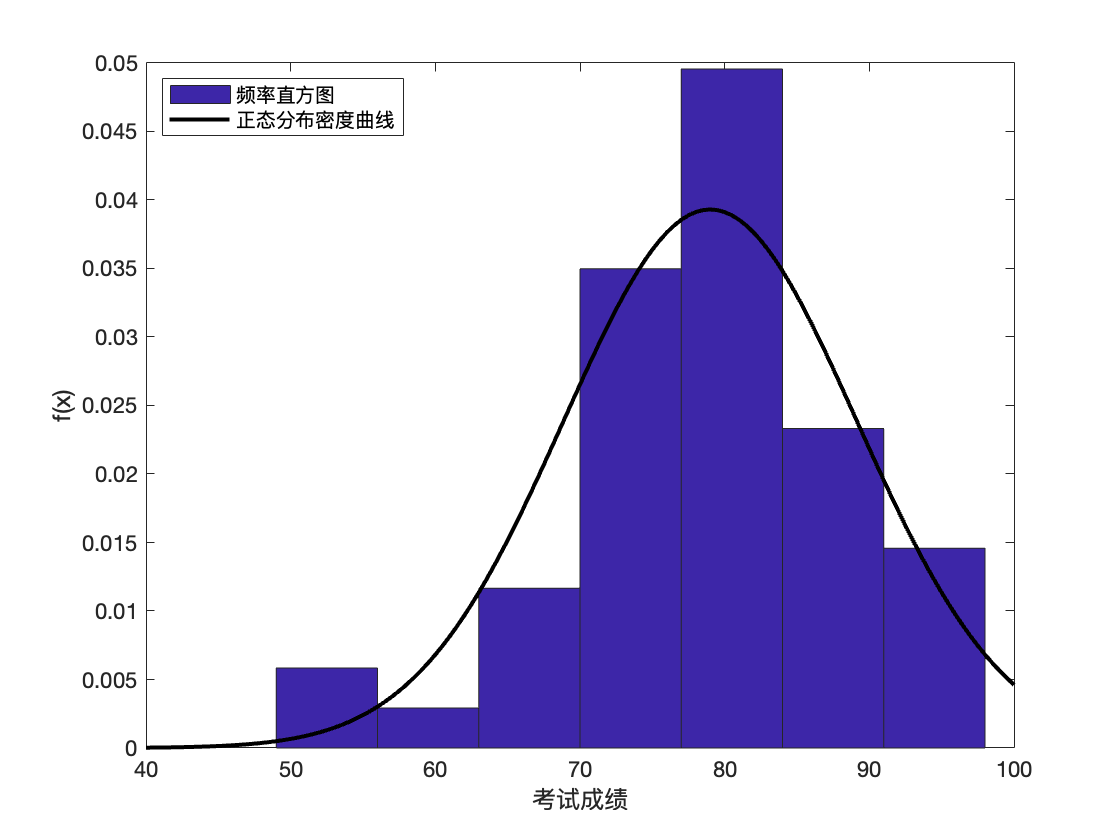

%% 频数（率）直方图
figure;
[f, xc] = ecdf(score);
ecdfhist(f, xc, 7);
xlabel('考试成绩');
ylabel('f(x)');
x = 40:0.5:100;
y = normpdf(x,mean(score),std(score));
hold on
plot(x,y,'k','LineWidth',2) 
legend('频率直方图','正态分布密度曲线','Location','NorthWest');

%% 经验分布函数图
figure;
[h,stats] = cdfplot(score)

h =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 49 49 63 63 64 64 69 69 70 70 71 71 72 72 73 73 74 74 75 75 76 76 77 77 78 78 79 79 80 80 81 81 82 82 83 83 84 84 85 85 87 87 88 88 89 89 90 90 91 91 92 92 94 94 95 95 98 98 Inf]
              YData: [1×60 double]
              ZData: [1×0 double]

  显示 所有属性


stats = 包含以下字段的 struct :
       min: 49
       max: 98
      mean: 79
    median: 80
       std: 10.1489


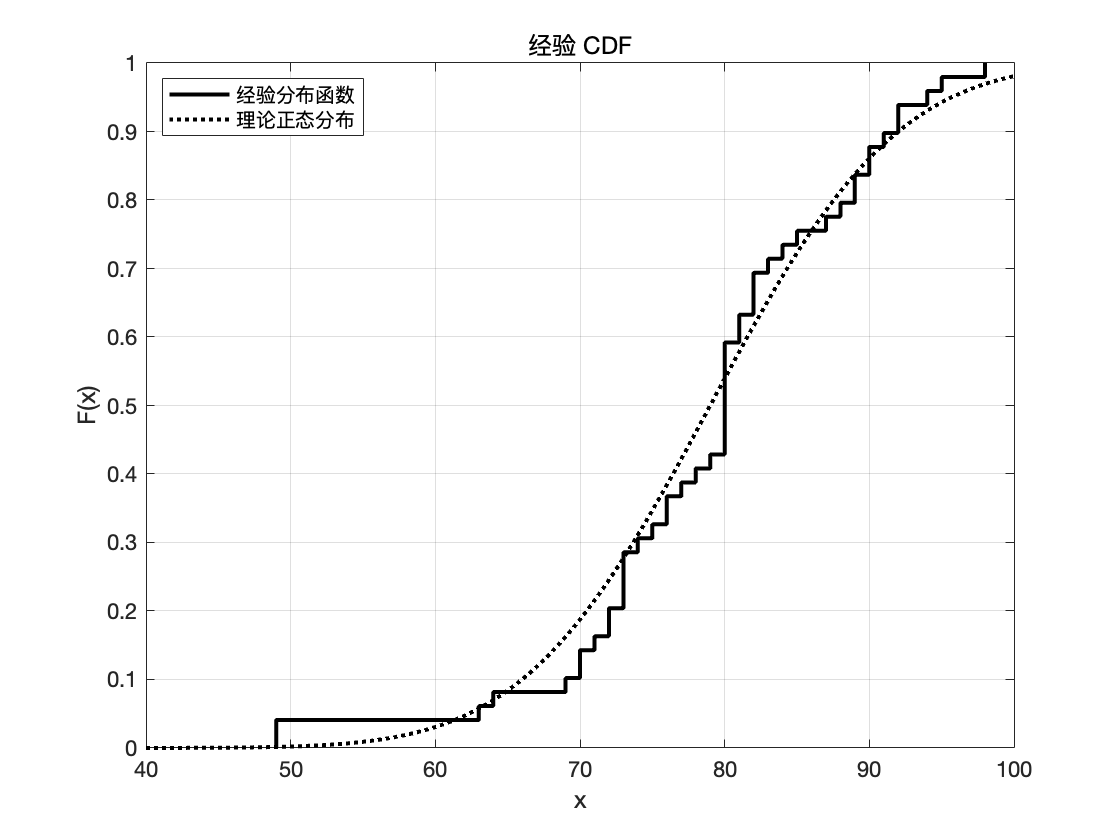

set(h,'color','k','LineWidth',2);
x = 40:0.5:100;
y = normcdf(x,stats.mean,stats.std);
hold on
plot(x,y,':k','LineWidth',2);
legend('经验分布函数','理论正态分布','Location','NorthWest');

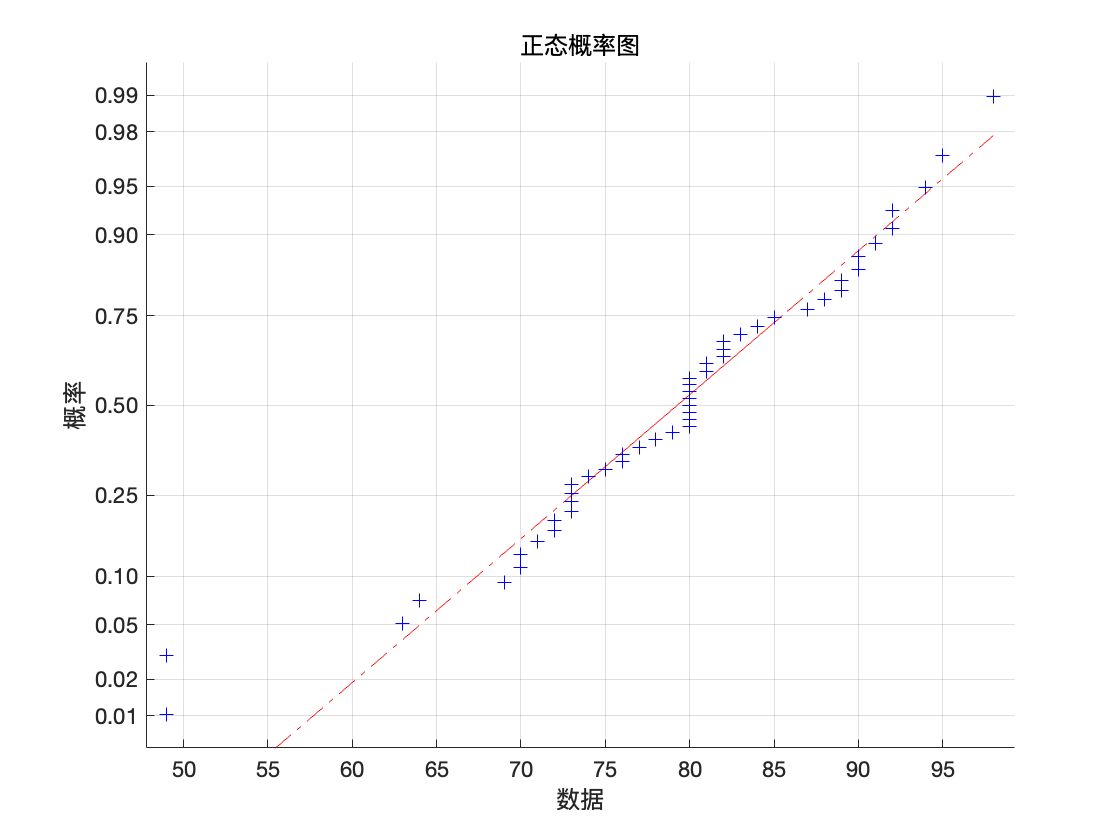

%% 正态概率图
figure;
normplot(score); 

%--------------------------------------------------------------------------
% 参数估计与假设检验
%--------------------------------------------------------------------------
%+++++++++++++++++++++++++调用normfit函数求解+++++++++++++++++++++++++++++++
x = [15.14  14.81  15.11  15.26  15.08  15.17  15.12  14.95  15.05  14.87];
[muhat,sigmahat,muci,sigmaci] = normfit(x,0.1)

muhat = 15.0560

sigmahat = 0.1397

muci =    14.9750
   15.1370


sigmaci =     0.1019
    0.2298



%++++++++++++++++++++++++++++调用mle函数求解++++++++++++++++++++++++++++++++
x = [15.14  14.81  15.11  15.26  15.08  15.17  15.12  14.95  15.05  14.87];
[mu_sigma,mu_sigma_ci] = mle(x,'distribution','norm','alpha',0.1)

mu_sigma =    15.0560    0.1325


mu_sigma_ci =    14.9750    0.1019
   15.1370    0.2298


%% examp18.3-1
%++++++++++++++++++++++++++++++++双侧检验++++++++++++++++++++++++++++++++++
x = [97  102  105  112  99  103  102  94  100  95  105  98  102  100  103];
[h,p,muci,zval] = ztest(x,100,2,0.05)

h = 1

p = 0.0282

muci =   100.1212  102.1455


zval = 2.1947


%++++++++++++++++++++++++++++++++单侧检验++++++++++++++++++++++++++++++++++
x = [97  102  105  112  99  103  102  94  100  95  105  98  102  100  103];
[h,p,muci,zval] = ztest(x,100,2,0.05,'right')

h = 1

p = 0.0141

muci =   100.2839       Inf


zval = 2.1947

%% examp18.3-2
x = [49.4  50.5  50.7  51.7  49.8  47.9  49.2  51.4  48.9];
[h,p,muci,stats] = ttest(x,50,0.05)

h = 0

p = 0.8961

muci =    48.9943   50.8945


stats = 包含以下字段的 struct :
    tstat: -0.1348
       df: 8
       sd: 1.2360


%% examp18.3-3
x = [20.1,  20.0,  19.3,  20.6,  20.2,  19.9,  20.0,  19.9,  19.1,  19.9];
y = [18.6,  19.1,  20.0,  20.0,  20.0,  19.7,  19.9,  19.6,  20.2];
alpha = 0.05;
tail = 'both';
vartype = 'equal';
[h,p,muci,stats] = ttest2(x,y,alpha,tail,vartype)

h = 0

p = 0.3191

muci =    -0.2346    0.6791


stats = 包含以下字段的 struct :
    tstat: 1.0263
       df: 17
       sd: 0.4713


%% examp18.3-4
x = [49.4  50.5  50.7  51.7  49.8  47.9  49.2  51.4  48.9];
var0 = 1.5;
alpha = 0.05;
tail = 'both';
[h,p,varci,stats] = vartest(x,var0,alpha,tail)

h = 0

p = 0.8383

varci =     0.6970    5.6072


stats = 包含以下字段的 struct :
    chisqstat: 8.1481
           df: 8


%% examp18.3-5
x = [20.1,  20.0,  19.3,  20.6,  20.2,  19.9,  20.0,  19.9,  19.1,  19.9];
y = [18.6,  19.1,  20.0,  20.0,  20.0,  19.7,  19.9,  19.6,  20.2];
alpha = 0.05;
tail = 'both';
[h,p,varci,stats] = vartest2(x,y,alpha,tail)

h = 0

p = 0.5798

varci =     0.1567    2.8001


stats = 包含以下字段的 struct :
    fstat: 0.6826
      df1: 9
      df2: 8
